clear
clc

system("g++ ./FiniteDifferences.cpp " + ...
    "-O2 -o ./FiniteDifferences.exe -Wall");

./FiniteDifferences.cpp: In function 'int main(int, const char**)':
./FiniteDifferences.cpp:83:27: warning: unused variable 'j_c0' [-Wunused-variable]
   83 |     int i_c0 = x_c0 / Dx, j_c0 = y_c0 / Dy;
      |                           ^~~~


N = 400

N = 500

M = N;
system(".\FiniteDifferences.exe " + string(N));

Traceback (most recent call last): 
  File "E:\John\Documents [External]\NTUA Files\\u0394\u03b9\u03c0\u03bb\u03c9\u03bc\u03b1\u03c4\u03b9\u03ba\u03ae\Thesis\Potential Field Solution\src\SparseSolver.py", line 16, in <module> 
    x = spsolve(A_sp, b) 
  File "C:\Users\John\miniforge3\lib\site-packages\pypardiso\scipy_aliases.py", line 44, in spsolve 
    solver._check_A(A) 
  File "C:\Users\John\miniforge3\lib\site-packages\pypardiso\pardiso_wrapper.py", line 205, in _check_A 
    raise ValueError('Matrix A is singular, because it contains empty {}(s)'.format(row_col)) 
ValueError: Matrix A is singular, because it contains empty row(s) 



v1.x = round((500 - 68.75)/1000 * N);
v1.y = round(500/1000 * N);
v2.x = round((500 + 68.75)/1000 * N);
v2.y = round(500/1000 * N);

v3.x = round((500 - 68.75)/1000 * N);
v3.y = round((500 + 100)/1000 * N);
v4.x = round((500 + 68.75)/1000 * N);
v4.y = round((500 + 100)/1000 * N);

x = load("x.txt");

DV1 = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))); %[V]
DV2 = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))); %[V]

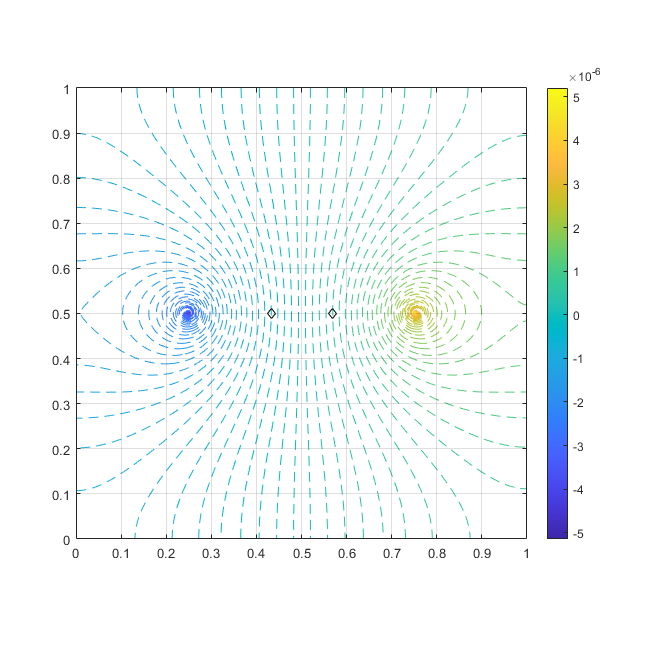

phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
    end
end

psi = zeros(M,N);
for i = 3:N
    for j = 3:M-1
        psi(j,i) = 1/3 * (4*psi(j-1,i) - psi(j-2,i) + (3*phi(j,i) - 4*phi(j,i-1) + phi(j,i-2)));
    end
end

figure("Position",[0,0,650,650]);
X_range = linspace(0,1,size(phi,2));
Y_range = linspace(0,1,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,100,'LineStyle',"--")
hold on
% contour(psi,100,'LineStyle',":", ...
%     'LineColor','k')
scatter(Dx*v1.x,Dy*v1.y,'kd')
scatter(Dx*v2.x,Dy*v2.y,'kd')
xticks(X_range(1) : X_range(end)/10 : X_range(end))
yticks(Y_range(1) : Y_range(end)/10 : Y_range(end))
hold off
grid on
axis equal
colorbar()


% mesh(psi)
% view([-75 10])